load("MobileSensorData/sensorlog_20230608_122237.mat")
position_timestamp=Position.Timestamp;
lat=Position.latitude;
long=Position.longitude;
position_timestamp=timeElapsed(position_timestamp);
earthCirc = 24901;
totaldis = 0;
sum_vel=0;
vel=0; %%velocity%%
t0=0;
x0=0;

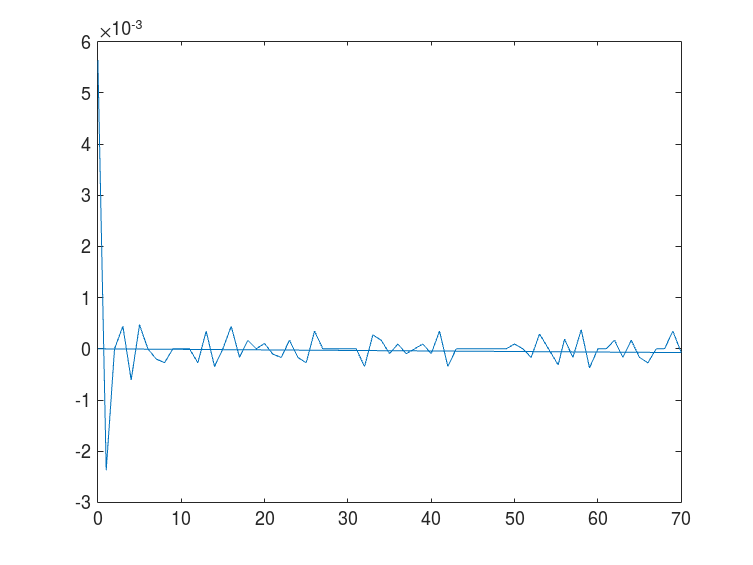

v=zeros(length(lat));
t=zeros(length(lat));
for i=1:(length(lat)-1)
    vel1=vel;
    lat1 = lat(i);
    lat2 = lat(i+1);
    long1=long(i);
    long2 = long(i+1);
    var = distance(lat1, long1 , lat2 , long2);
    dis = (var/360)*earthCirc;
    vel=(dis-x0)/(position_timestamp(i+1)-t0);
    sum_vel = sum_vel + vel;
    x0=dis;
    t0=position_timestamp(i);
    v(i)=vel;
    t(i)=position_timestamp(i);
    if vel>vel1
        max_vel=vel; %%maximum velocity%%
    else
        max_vel=vel1;
    end
    totaldis = totaldis + dis;

end
plot(t(1:1:71),v(1:1:71))

We are now printing the mean velocity

mean_vel= sum_vel/(length(lat)-1); %%mean_velocity%%
mean_vel = mean_vel * 1609 %% meter/second %%

mean_vel = 0.0711

We are now printing the total distance and total steps

totaldis = totaldis * 1609 %% meters %%

totaldis = 86.1813

steps = totaldis/0.762

steps = 113.0988